# Thermodynamically constrain a metabolic model

## **Author: Ronan Fleming, Leiden University**

## **Reviewers: **

## INTRODUCTION

In flux balance analysis of genome scale stoichiometric models of metabolism, the principal constraints are uptake or secretion rates, the steady state mass conservation assumption and reaction directionality. Von Bertylanffy [1,4] is a set of methods for (i) quantitative estimation of thermochemical parameters for metabolites and reactions using the component contribution method [3], (ii) quantitative assignment of reaction directionality in a multi-compartmental genome scale model based on an application of the second law of thermodynamics to each reaction [2], (iii) analysis of thermochemical parameters in a network context, and (iv) thermodynamically constrained flux balance analysis. The theoretical basis for each of these methods is detailed within the cited papers.

## PROCEDURE

## Configure the environment

All the installation instructions are in a separate .md file named vonBertalanffy.md in docs/source/installation

With all dependencies installed correctly, we configure our environment, verfy all dependencies, and add required fields and directories to the matlab path.


initVonBertalanffy

ChemAxon Marvin Beans is installed and working.


# Select the model

This tutorial is tested for the E. coli model iAF1260 and the human metabolic model Recon3Dmodel. However, only the data for the former is provided within the COBRA Toolbox as it is used for testing von Bertylanffy. However, the figures generated below are most suited to plotting results for Recon3D, so they may not be so useful for iAF1260.  The Recon3D example uses values from literature for input variables where they are available.

%modelName = 'iAF1260';
%modelName='Ec_iAF1260_flux1'; 
% uncomment this line and comment the line below if you want to use the other model-  currently will not work without changes
modelName='Recon3DModel_301'; 

## Load a model

Load a model, and save it as the original model in the workspace, unless it is already loaded into the workspace. 

clear model
global CBTDIR
modelFileName = [modelName '.mat']

modelFileName = 'Recon3DModel_301.mat'



modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded

switch modelName
    case 'Ec_iAF1260_flux1'
        modelFileName = [modelName '.xml']
        model = readCbModel(modelFileName);
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[Cytosol]', model.mets))=0; % One reaction needing charge balancing
        
    case 'iAF1260'
        model = readCbModel(modelFileName);
        model.mets = cellfun(@(mets) strrep(mets,'_c','[c]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_e','[e]'),model.mets,'UniformOutput',false);
        model.mets = cellfun(@(mets) strrep(mets,'_p','[p]'),model.mets,'UniformOutput',false);
        bool = strcmp(model.mets,'lipa[c]old[c]');
        model.mets{bool}='lipa_old_[c]';
        bool = strcmp(model.mets,'lipa[c]old[e]');
        model.mets{bool}='lipa_old_[e]';
        bool = strcmp(model.mets,'lipa[c]old[p]');
        model.mets{bool}='lipa_old_[p]';
        if model.S(952, 350)==0
            model.S(952, 350)=1; % One reaction needing mass balancing in iAF1260
        end
        model.metCharges(strcmp('asntrna[c]', model.mets))=0; % One reaction needing charge balancing
        
    case 'Recon3DModel_Dec2017'
      model = readCbModel(modelFileName);
      model.csense(1:size(model.S,1),1)='E';
      %Hack for thermodynamics
      model.metFormulas{strcmp(model.mets,'h[i]')}='H';
      model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
      if isfield(model,'metCharge')
          model.metCharges = double(model.metCharge);
          model=rmfield(model,'metCharge');
      end
      modelOrig = model;
   case 'Recon3DModel_301'
      model = readCbModel(modelFileName);
          %Hack for thermodynamics
      model.metFormulas(cellfun('isempty',model.metFormulas)) = {'R'};
      modelOrig = model;
    otherwise
            error('setup specific parameters for your model')
end

Each model.subSystems{x} has been changed to a character array.


## Set the directory containing the results

switch modelName
    case 'Ec_iAF1260_flux1'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'iAF1260'
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results'];
    case 'Recon3DModel_Dec2017'
        basePath='~/work/sbgCloud';
        resultsPath=[basePath '/programReconstruction/projects/recon2models/results/thermo/' modelName];
        resultsBaseFileName=[resultsPath filesep modelName '_' datestr(now,30) '_'];
    case 'Recon3DModel_301'
        basePath='~/work/sbgCloud';
        resultsPath=which('tutorial_vonBertalanffy.mlx');
        resultsPath=strrep(resultsPath,'/tutorial_vonBertalanffy.mlx','');
        resultsPath=[resultsPath filesep modelName '_results'];
        resultsBaseFileName=[resultsPath filesep modelName '_results_'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the directory containing molfiles

switch modelName
    case 'Ec_iAF1260_flux1'
        molFileDir = 'iAF1260Molfiles';
    case 'iAF1260'
        molFileDir = 'iAF1260Molfiles';
    case 'Recon3DModel_Dec2017'
        molFileDir = [basePath '/data/metDatabase/explicit/molFiles'];
        %molFileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBimplicitHMol'];
        %molFileDir = [basePath '/programModelling/projects/atomMapping/results/molFilesDatabases/DBexplicitHMol'];
    case 'Recon3DModel_301'
        molFileDir = [basePath '/data/metDatabase/explicit/molFiles']; 
        molFileDir = [basePath '/code/fork-ctf/mets/molFiles'];
    otherwise
        error('setup specific parameters for your model')
end

## Set the thermochemical parameters for the model

switch modelName
    case 'Ec_iAF1260_flux1'
        T = 310.15; % Temperature in Kelvin
        compartments = {'Cytosol'; 'Extra_organism'; 'Periplasm'}; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV        
    case 'iAF1260'
        T = 310.15; % Temperature in Kelvin
        compartments = ['c'; 'e'; 'p']; % Cell compartment identifiers
        ph = [7.7; 7.7; 7.7]; % Compartment specific pH
        is = [0.25; 0.25; 0.25]; % Compartment specific ionic strength in mol/L
        chi = [0; 90; 90]; % Compartment specific electrical potential relative to cytosol in mV
    case 'Recon3DModel_Dec2017'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    case 'Recon3DModel_301'
        % Temperature in Kelvin
        T = 310.15; 
        % Cell compartment identifiers
        compartments = ['c'; 'e'; 'g'; 'l'; 'm'; 'n'; 'r'; 'x';'i']; 
        % Compartment specific pH
        ph = [7.2; 7.4; 6.35; 5.5; 8; 7.2; 7.2; 7; 7.2]; 
        % Compartment specific ionic strength in mol/L
        is = 0.15*ones(length(compartments),1); 
        % Compartment specific electrical potential relative to cytosol in mV
        chi = [0; 30; 0; 19; -155; 0; 0; -2.303*8.3144621e-3*T*(ph(compartments == 'x') - ph(compartments == 'c'))/(96485.3365e-6); 0]; 
    otherwise
        error('setup specific parameters for your model')
end

## Set the default range of metabolite concentrations

switch modelName
    case 'Ec_iAF1260_flux1'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'iAF1260'
        concMinDefault = 1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault = 0.02; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=[];
    case 'Recon3DModel_Dec2017'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    case 'Recon3DModel_301'
        concMinDefault=1e-5; % Lower bounds on metabolite concentrations in mol/L
        concMaxDefault=1e-2; % Upper bounds on metabolite concentrations in mol/L
        metBoundsFile=which('HumanCofactorConcentrations.txt');%already in the COBRA toolbox
    otherwise
        error('setup specific parameters for your model')
end

## Set the desired confidence level for estimation of thermochemical parameters

The confidence level for estimated standard transformed reaction Gibbs energies is used to quantitatively assign reaction directionality.

switch modelName
    case 'Ec_iAF1260_flux1'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol    
    case 'iAF1260'
        confidenceLevel = 0.95; 
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    case 'Recon3DModel_Dec2017'
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
    otherwise
        confidenceLevel = 0.95;
        DrGt0_Uncertainty_Cutoff = 20; %KJ/KMol
end

## Prepare folder for results

if ~exist(resultsPath,'dir')
    mkdir(resultsPath)
end
cd(resultsPath)

## Set the print level and decide to record a diary or not (helpful for debugging)

printLevel=2;

diary([resultsPath filesep 'diary.txt'])

# Setup a thermodynamically constrained model

## Read in the metabolite bounds

setDefaultConc=1;
setDefaultFlux=0;
rxnBoundsFile=[];
model=readMetRxnBoundsFiles(model,setDefaultConc,setDefaultFlux,concMinDefault,concMaxDefault,metBoundsFile,rxnBoundsFile,printLevel);

Reading metabolite conc bounds from: /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/experimentalData/metaboliteConcentrations/HumanCofactorConcentrations.txt
              adp[c]	     1e-07	    0.0019
              adp[m]	    0.0026	    0.0094
              amp[c]	     1e-07	    0.0012
              atp[c]	   0.00129	    0.0049
              atp[m]	    0.0028	    0.0204
              coa[c]	  2.92e-05	 0.0001168
              coa[m]	    0.0022	    0.0039
              na1[c]	     1e-07	     0.025
              na1[e]	    0.1326	    0.1554
              nad[c]	0.00010546	 0.0007572
              nad[m]	    0.0005	    0.0075
             nadh[c]	9.2574e-07	0.00038294
             nadh[m]	     1e-07	    0.0011
             nadp[c]	     1e-07	5.8284e-06
             nadp[m]	     1e-07	    0.0015
            nadph[c]	     1e-07	0.00037523
            nadph[m]	     1e-07	    0.0042
              nh4[c]	    0.0007	    0.0009
               pi[c]	     0.001	    0.0063


## Check inputs

model = configureSetupThermoModelInputs(model,T,compartments,ph,is,chi,concMinDefault,concMaxDefault,confidenceLevel);


Field metCompartments is missing from model structure. Attempting to create it.
Attempt to create field metCompartments successful.



## Check elemental balancing of metabolic reactions

ignoreBalancingOfSpecifiedInternalReactions=1;
if ~exist('massImbalance','var')
    if isfield(model,'Srecon')
        model.S=model.Srecon;
    end
    % Check for imbalanced reactions
    fprintf('\nChecking mass and charge balance.\n');
    %Heuristically identify exchange reactions and metabolites exclusively involved in exchange reactions
    if ~isfield(model,'SIntMetBool')  ||  ~isfield(model,'SIntRxnBool') || ignoreBalancingOfSpecifiedInternalReactions
        %finds the reactions in the model which export/import from the model
        %boundary i.e. mass unbalanced reactions
        %e.g. Exchange reactions
        %     Demand reactions
        %     Sink reactions
        model = findSExRxnInd(model,[],printLevel);
    end
    
    if ignoreBalancingOfSpecifiedInternalReactions
        [nMet,nRxn]=size(model.S);
        ignoreBalancingMetBool=false(nMet,1);
        for m=1:nMet
%             if strcmp(model.mets{m},'Rtotal3coa[m]')
%                 pause(0.1);
%             end
            if ~isempty(model.metFormulas{m})
                ignoreBalancingMetBool(m,1)=numAtomsOfElementInFormula(model.metFormulas{m},'FULLR');
            end
        end
        ignoreBalancingRxnBool=getCorrespondingCols(model.S,ignoreBalancingMetBool,model.SIntRxnBool,'inclusive');
        SIntRxnBool=model.SIntRxnBool;
        model.SIntRxnBool=model.SIntRxnBool & ~ignoreBalancingRxnBool;
    end
    
    printLevelcheckMassChargeBalance=-1;  % -1; % print problem reactions to a file
    %mass and charge balance can be checked by looking at formulas
    [massImbalance,imBalancedMass,imBalancedCharge,imBalancedRxnBool,Elements,missingFormulaeBool,balancedMetBool]...
        = checkMassChargeBalance(model,printLevelcheckMassChargeBalance,resultsBaseFileName);
    model.balancedRxnBool=~imBalancedRxnBool;
    model.balancedMetBool=balancedMetBool;
    model.Elements=Elements;
    model.missingFormulaeBool=missingFormulaeBool;
    
    %reset original boolean vector
    if ignoreBalancingOfSpecifiedInternalReactions
        model.SIntRxnBool=SIntRxnBool;
    end
end


Checking mass and charge balance.


Assuming biomass reaction is: biomass_maintenance
ATP demand reaction is not considered an exchange reaction by default. It should be mass balanced:
DM_atp_c_	h2o[c] + atp[c] 	->	h[c] + adp[c] + pi[c] 


There are mass imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/Recon3DModel_301_results_mass_imbalanced_reactions.txt
There are mass balanced, but charge imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/Recon3DModel_301_results_charge_imbalanced_reactions.txt


## Add InChI to model

%[model, pKaErrorMets] = setupComponentContribution(model,molFileDir);
model = addInchiToModel(model, molFileDir, 'sdf', printLevel);

Creating MetStructures.sdf from molfiles.
Percentage of metabolites without mol files: 9.1%
Converting SDF to InChI strings.
5835 = number of model metabolites
5835 ... with mol files
0 ... without mol files
4949 ... with nonstandard inchi
886 ... without nonstandard inchi
102 ... compositie inchi removed


## Add pseudoisomers to model

[model, nonphysicalMetBool, pKaErrorMetBool] = addPseudoisomersToModel(model, printLevel);

Estimating metabolite pKa values.

ChemAxon's pKa calculator plugin returned an error for 2 metabolites:
    'CE6252'          'InChI=1S/C5H3N4O3/c10-3-1-2(7-4(11)6-1)8-5(12)9-3/h(H3,6,7,8,9,10,11,12)'                                                                           
    'pchol2ste_hs'    'InChI=1S/C26H55NO7P/c1-5-6-7-8-9-10-11-12-13-14-15-16-17-18-19-20-26(29)32-23-25(28)24-34-35(30,31)33-22-21-27(2,3)4/h25,28H,5-24H2,1-4H3,(H,30,31)'

Assuming that metabolite species in model.metFormulas are representative for metabolites where pKa could not be estimated.
5835 = number of model metabolites
222 = number of nonphysical model metabolites
3 = number of model metabolites with pKa error


## Load the training data for the component contribution method

% load the training data (from TECRDB, Alberty, etc.)
%trainingModel = loadTrainingData();
forceMolReplacement=0;
trainingModel = updateTrainingModel([],[],forceMolReplacement,printLevel);

Successfully added 3914 values from TECRDB
Successfully added 223 formation energies
Successfully added 13 redox potentials
mol2inchi: no annotation in C00080
createInChIStruct: no molecule identifier in C00080
mol2inchi: no annotation in C00080
mol2inchi: no annotation in C00080
mol2inchi: no annotation in C00080
mol2inchi: could not generate inchi for C00125
obabel: Alias R was not chemically interpreted
createInChIStruct: no molecule identifier in C00125
mol2inchi: could not generate inchi for C00125
obabel: Alias R was not chemically interpreted
mol2inchi: could not generate inchi for C00125
obabel: Alias R was not chemically interpreted
mol2inchi: could not generate inchi for C00125
obabel: Alias R was not chemically interpreted
mol2inchi: could not generate inchi for C00126
obabel: Alias R was not chemically interpreted
createInChIStruct: no molecule identifier in C00126
mol2inchi: could not generate inchi for C00126
obabel: Alias R was not chemically interpreted
mol2inchi: could

Check that the training data reactions are elementally balanced

% use the chemical formulas from the InChIs to verify that each and every
% reaction is balanced.
%trainingModel = balanceReactionsInTrainingData(trainingModel);
fileName =[resultsPath filesep 'trainingData_'];
[training_massImbalance, training_imBalancedMass, training_imBalancedCharge, training_imBalancedRxnBool, elements, training_missingFormulaeBool, training_balancedMetBool]...
    = checkMassChargeBalance(trainingModel, -1, fileName);

There are mass imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/trainingData_mass_imbalanced_reactions.txt
There are mass balanced, but charge imbalanced reactions, see /home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/vonBertalanffy/Recon3DModel_301_results/trainingData_charge_imbalanced_reactions.txt


Identify the reactions that (a) do not involve metabolites without formulae, (b) are mass imbalanced ignoring H, (c ) are not formation reactions.

removeBool = ~any(isnan(training_massImbalance),2) & sum(training_massImbalance(:,~strcmp(elements,'H')),2)~=0 & (sum(trainingModel.S~=0,1)~=1)';
find(removeBool)

ans =      1
   243
   609
   722
   723
   724
   725
   726
   727
   728


T=array2table([find(removeBool),training_massImbalance(removeBool,:)],'VariableNames',['j',elements]);
disp(T)

     j       H     C     O     P    S    N    Mg    X    Fe    Zn    Co    Ca    Y    I    Na    Cl    K    R    FULLR
    ____    ___    __    __    _    _    _    __    _    __    __    __    __    _    _    __    __    _    _    _____

       1      1     0     1    0    0    0    0     0    0     0     0     0     

Get training data pKa's

% get the pKas for the compounds in the training data (using ChemAxon)
%trainingModel.kegg_pKa = getTrainingDatapKas(trainingModel);

## Create Group Incidence Matrix

Match between the metabolites in the model and the metabolites in the training model

mappingScore = getMappingScores(model, trainingModel);

Mapping model metabolites to training model metabolites


Create the group incidence matrix (G) for the combined set of all metabolites.

trainingModel = createGroupIncidenceMatrix(model, trainingModel,mappingScore,2);

Creating group incidence matrix
python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H14N3O8P/c10-5-1-2-12(9(15)11-5)8-7(14)6(13)4(20-8)3-19-21(16,17)18/h1-2,4,6-8,13-14H,3H2,(H2,10,11,15)(H2,16,17,18)/p-2/t4-,6-,7-,8-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H16N3O14P3/c10-5-1-2-12(9(15)11-5)8-7(14)6(13)4(24-8)3-23-28(19,20)26-29(21,22)25-27(16,17)18/h1-2,4,6-8,13-14H,3H2,(H,19,20)(H,21,22)(H2,10,11,15)(H2,16,17,18)/p-3/t4-,6-,7-,8-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H15N3O11P2/c10-5-1-2-12(9(15)11-5)8-7(14)6(13)4(22-8)3-21-25(19,20)23-24(16,17)18/h1-2,4,6-8,13-14H,3H2,(H,19,20)(H2,10,11,15)(H2,16,17,18)/p-2/t4-,6-,7-,8-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H14N3O7P/c10-7-1-2-12(9(14)11-7)8-3-5(13)6(19-8)4-18-20(15,16)17/h1-2,5-6,8,13H,3-4H2,(H2,10,11,14)(H2,15,16,17)/p-2/t5-,6+,8+/m0/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C14H26N4O11P2/c1-18(2,3)6-7-26-30(22,23)29-31(24,25)27-8-9-11(19)12(20)13(28-9)17-5-4-10(15)16-14(17)21/h4-5,9,11-13,19-20H,6-8H2,1-3H3,(H3-,15,16,21,22,23,24,25)/p-1/t9-,11-,12-,13-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C18H22O2/c1-18-9-8-14-13-5-3-12(19)10-11(13)2-4-15(14)16(18)6-7-17(18)20/h3,5,10,14-16,19H,2,4,6-9H2,1H3/t14-,15-,16+,18+/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H13N3O5/c10-5-1-2-12(9(16)11-5)8-7(15)6(14)4(3-13)17-8/h1-2,4,6-8,13-15H,3H2,(H2,10,11,16)/t4-,6-,7-,8-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C15H25N3O16P2/c16-7-1-2-18(15(25)17-7)13-11(23)9(21)6(31-13)4-30-35(26,27)34-36(28,29)33-14-12(24)10(22)8(20)5(3-19)32-14/h1-2,5-6,8-14,19-24H,3-4H2,(H,26,27)(H,28,29)(H2,16,17,25)/p-2/t5-,6-,8-,9-,10+,11-,12-,13-,14-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C11H20N4O11P2/c12-2-4-23-27(19,20)26-28(21,22)24-5-6-8(16)9(17)10(25-6)15-3-1-7(13)14-11(15)18/h1,3,6,8-10,16-17H,2,4-5,12H2,(H,19,20)(H,21,22)(H2,13,14,18)/p-1/t6-,8-,9-,10-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C9H15N3O10P2/c10-7-1-2-12(9(14)11-7)8-3-5(13)6(21-8)4-20-24(18,19)22-23(15,16)17/h1-2,5-6,8,13H,3-4H2,(H,18,19)(H2,10,11,14)(H2,15,16,17)/p-2/t5-,6+,8+/m0/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C18H24O2/c1-18-9-8-14-13-5-3-12(19)10-11(13)2-4-15(14)16(18)6-7-17(18)20/h3,5,10,14-17,19-20H,2,4,6-9H2,1H3/t14-,15-,16+,17+,18+/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C12H17N4O4PS/c1-8-11(3-4-20-21(17,18)19)22-7-16(8)6-10-5-14-9(2)15-12(10)13/h5,7H,3-4,6H2,1-2H3,(H3-,13,14,15,17,18,19)/p-1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C3H9NO/c1-4(2,3)5/h1-3H3": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C15H25N3O14P2/c1-6-7(19)4-8(20)14(29-6)31-34(26,27)32-33(24,25)28-5-9-11(21)12(22)13(30-9)18-3-2-10(16)17-15(18)23/h2-3,6-9,11-14,19-22H,4-5H2,1H3,(H,24,25)(H,26,27)(H2,16,17,23)/p-2/t6-,7+,8-,9-,11-,12-,13-,14-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C15H25N3O14P2/c1-6-7(19)4-8(20)14(29-6)31-34(26,27)32-33(24,25)28-5-9-11(21)12(22)13(30-9)18-3-2-10(16)17-15(18)23/h2-3,6-9,11-14,19-22H,4-5H2,1H3,(H,24,25)(H,26,27)(H2,16,17,23)/p-2/t6-,7+,8+,9-,11-,12-,13-,14-/m1/s1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C6H7N2O3/c9-5(10)2-1-4-6(11)8-3-7-4/h3H,1-2H2,(H,9,10)(H,7,8,11)/q-1": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C6H11N3O7P2/c1-4-8-2-5(6(7)9-4)3-15-18(13,14)16-17(10,11)12/h2H,3H2,1H3,(H,13,14)(H2,7,8,9)(H2,10,11,12)/p-2": Signal 127


python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/Na/q+1": Signal 127
python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C17H19N3O4S/c1-10-15(18-7-11(8-21)16(10)24-3)9-25(22)17-19-13-5-4-12(23-2)6-14(13)20-17/h4-7,21H,8-9H2,1-3H3,(H,19,20)": Signal 127
python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i "InChI=1S/C39H51N11O18/c40-20(33(59)60)5-9-24(51)19(13-27(54)55)39(25(52)10-6-21(41)34(61)62,37(67)68-28(56)12-8-23(43)36(65)66)50(26(53)11-7-22(42)35(63)64)32(58)16-1-3-17(4-2-16)45-14-18-15-46-30-29(47-18)31(57)49-38(44)48-30/h1-4,18-23,47H,5-15,40-43H2,(H10,44,45,46,48,49,54,55,57,58,59,60,61,62,63,64,65,66)/p-6/t18?,19?,20?,21?,22?,23?,39-/m0/s1": Signal 127
python2 /home/rfleming/work/sbgCloud/code/fork-cobratoolbox/src/analysis/thermo/groupContribution/inchi2gv.py -s -i

fprintf('%u%s\n',nnz(trainingModel.trainingMetBool),' = number of training metabolites')

672 = number of training metabolites


fprintf('%u%s\n',nnz(trainingModel.trainingMetBool & trainingModel.groupDecomposableBool),' ... of which are group decomposable.')

569 ... of which are group decomposable.


fprintf('%u%s\n',nnz(trainingModel.trainingMetBool & ~trainingModel.groupDecomposableBool),' ... of which are not group decomposable.')

103 ... of which are not group decomposable.



fprintf('%u%s\n',nnz(~trainingModel.trainingMetBool),' = number of test metabolites')

2525 = number of test metabolites


fprintf('%u%s\n',nnz(~trainingModel.trainingMetBool & trainingModel.groupDecomposableBool),' ... of which are group decomposable.')

1833 ... of which are group decomposable.


fprintf('%u%s\n',nnz(~trainingModel.trainingMetBool & ~trainingModel.groupDecomposableBool),' ... of which are not group decomposable.')

692 ... of which are not group decomposable.


fprintf('%u%s\n',nnz(~trainingModel.trainingMetBool & ~trainingModel.groupDecomposableBool),' ... of which are not group decomposable.')

692 ... of which are not group decomposable.


Reverse Legendre Transform to the training data

% apply the reverse Legendre transform for the relevant training observations (typically
% apparent reaction Keq from TECRDB)
use_model_pKas_by_default = true;
trainingModel = reverseTransformTrainingData(model, trainingModel, use_model_pKas_by_default);

Performing reverse Legendre transform


## Call the component contribution method

Running Component Contribution method


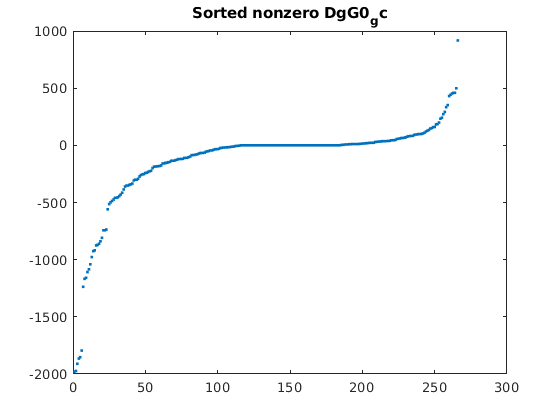

if ~isfield(model,'DfG0')
    [model,solution] = componentContribution(model,trainingModel);
end

## Setup a thermodynamically constrained model

if ~isfield(model,'DfGt0')
    model = setupThermoModel(model,confidenceLevel);
end


Estimating standard transformed Gibbs energies of formation.

Estimating bounds on transformed Gibbs energies.
Additional effect due to possible change in chemical potential of Hydrogen ions for transport reactions.
Additional effect due to possible change in electrical potential for transport reactions.


## Generate a model with reactants instead of major microspecies

if ~isfield(model,'Srecon') 
    printLevel_pHbalanceProtons=-1;
    model=pHbalanceProtons(model,massImbalance,printLevel_pHbalanceProtons,resultsBaseFileName);
end

## Determine quantitative directionality assignments

if ~exist('directions','var')
    fprintf('Quantitatively assigning reaction directionality.\n');
    [modelThermo, directions] = thermoConstrainFluxBounds(model,confidenceLevel,DrGt0_Uncertainty_Cutoff,printLevel);
end

Quantitatively assigning reaction directionality.


The following reactions have DrGtMax=DrGtMin=0:
ACYP


## Analyse thermodynamically constrained model

Choose the cutoff for probablity that reaction is reversible

cumNormProbCutoff=0.2;

Build Boolean vectors with reaction directionality statistics

[modelThermo,directions]=directionalityStats(modelThermo,directions,cumNormProbCutoff,printLevel);

Qualitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
      5208	 forward reconstruction assignment.
         4	 reverse reconstruction assignment.
      3579	 reversible reconstruction assignment.

Quantitative internal reaction directionality:
      8791	 internal reconstruction reaction directions.
       670	 of which have a thermodynamic assignment.
      8121	 of which have no thermodynamic assignment.
        17	 forward thermodynamic only assignment.
         4	 reverse thermodynamic only assignment.
       649	 reversible thermodynamic only assignment.

Qualitiative vs Quantitative:
       462	 Reversible -> Reversible
         7	 Reversible -> Forward
         4	 Reversible -> Reverse
      3106	 Reversible -> Uncertain
        10	 Forward -> Forward
         0	 Forward -> Reverse
       187	 Forward -> Reversible
      5011	 Forward -> Uncertain
         0	 Reverse -> Reverse
         0	 Reverse -> Forward
         0	 Reverse 

% directions    a structue of boolean vectors with different directionality
%               assignments where some vectors contain subsets of others
%
% qualtiative -> quantiative changed reaction directions
%   .forward2Forward
%   .forward2Reverse
%   .forward2Reversible
%   .forward2Uncertain
%   .reversible2Forward
%   .reversible2Reverse
%   .reversible2Reversible
%   .reversible2Uncertain
%   .reverse2Forward
%   .reverse2Reverse
%   .reverse2Reversible
%   .reverse2Uncertain
%   .tightened
%
% subsets of qualtiatively forward  -> quantiatively reversible 
%   .forward2Reversible_bydGt0
%   .forward2Reversible_bydGt0LHS
%   .forward2Reversible_bydGt0Mid
%   .forward2Reversible_bydGt0RHS
% 
%   .forward2Reversible_byConc_zero_fixed_DrG0
%   .forward2Reversible_byConc_negative_fixed_DrG0
%   .forward2Reversible_byConc_positive_fixed_DrG0
%   .forward2Reversible_byConc_negative_uncertain_DrG0
%   .forward2Reversible_byConc_positive_uncertain_DrG0

Write out reports on directionality changes for individual reactions to the results folder.

fprintf('%s\n','directionalityChangeReport...');

directionalityChangeReport...


directionalityChangeReport(modelThermo,directions,cumNormProbCutoff,printLevel,resultsBaseFileName)

Generate pie charts with proportions of reaction directionalities and changes in directionality

fprintf('%s\n','directionalityStatFigures...');

directionalityStatFigures...


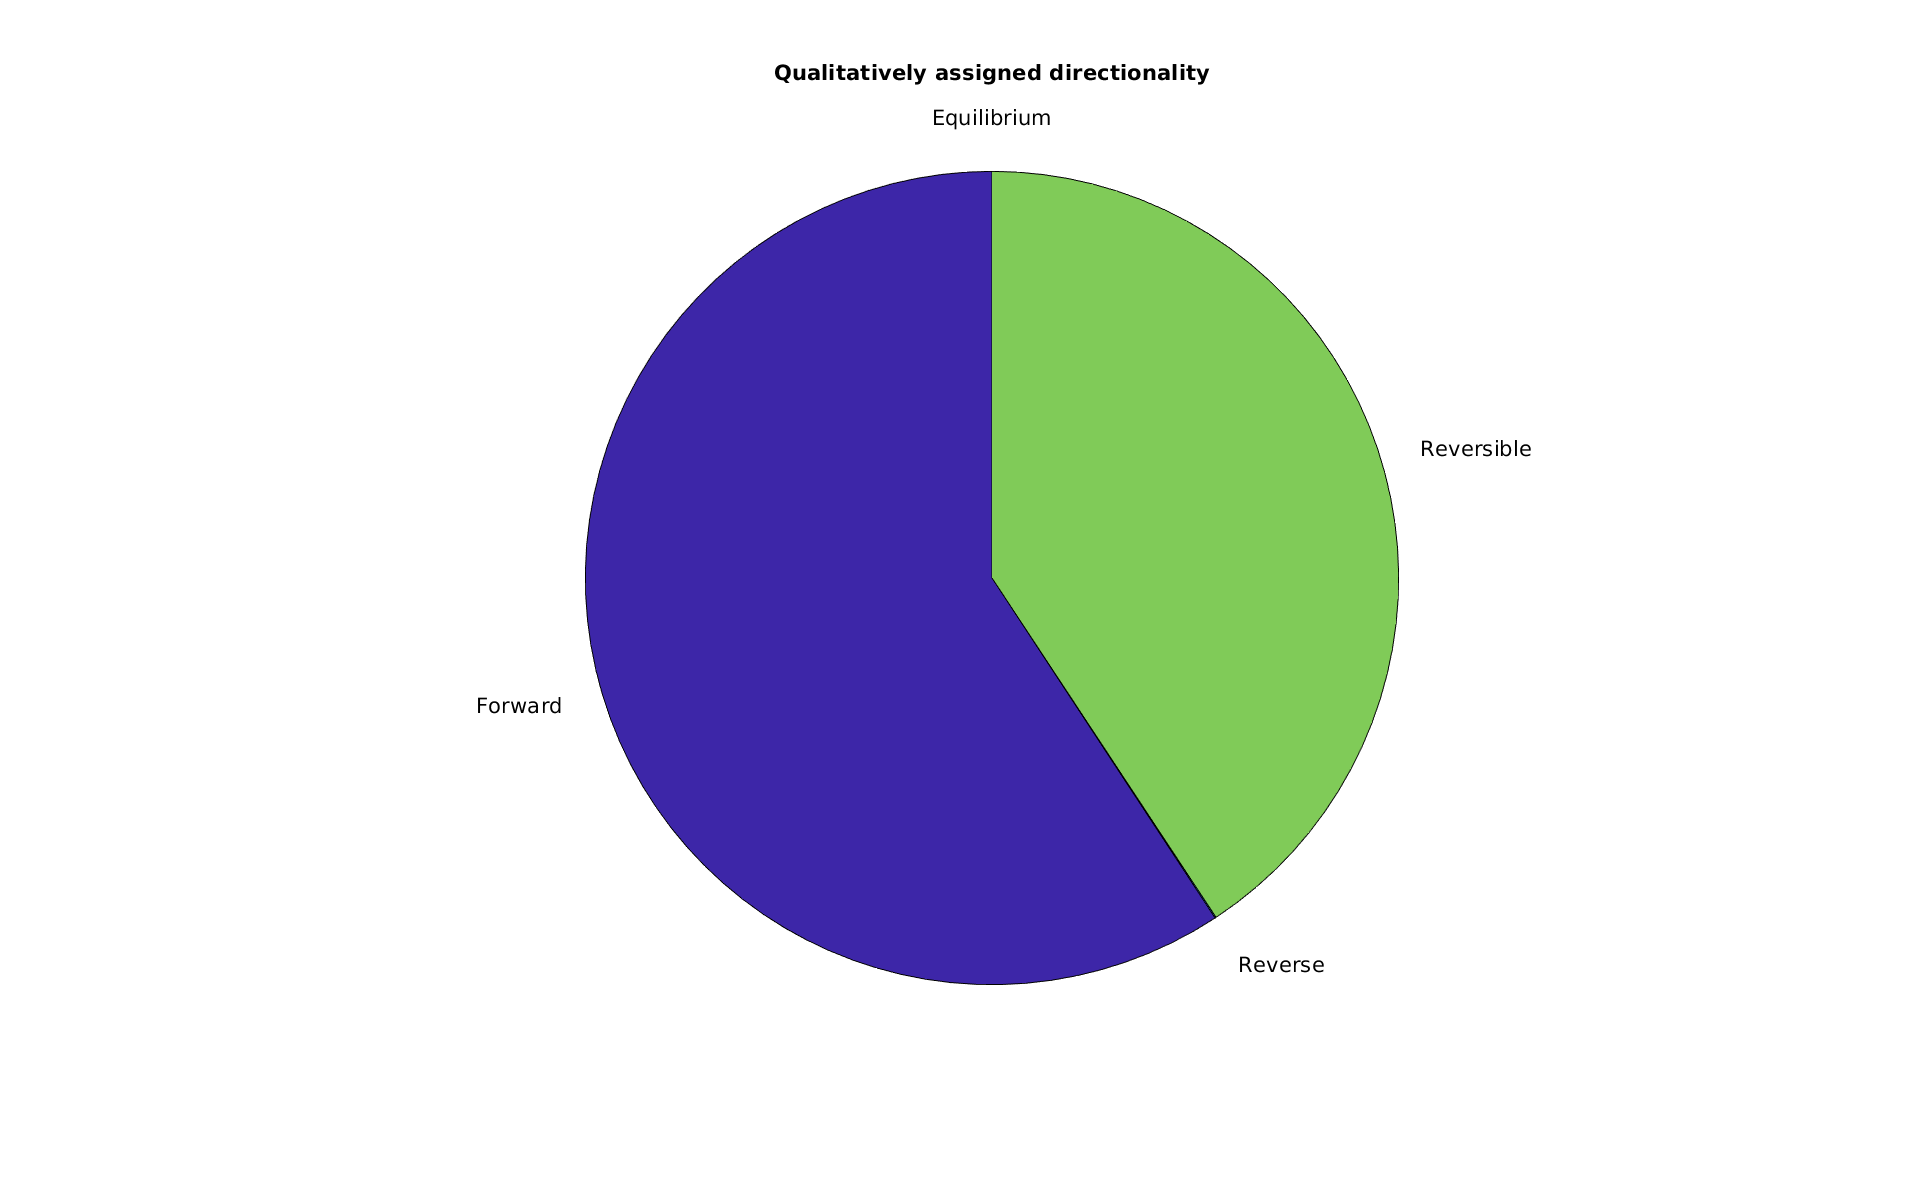

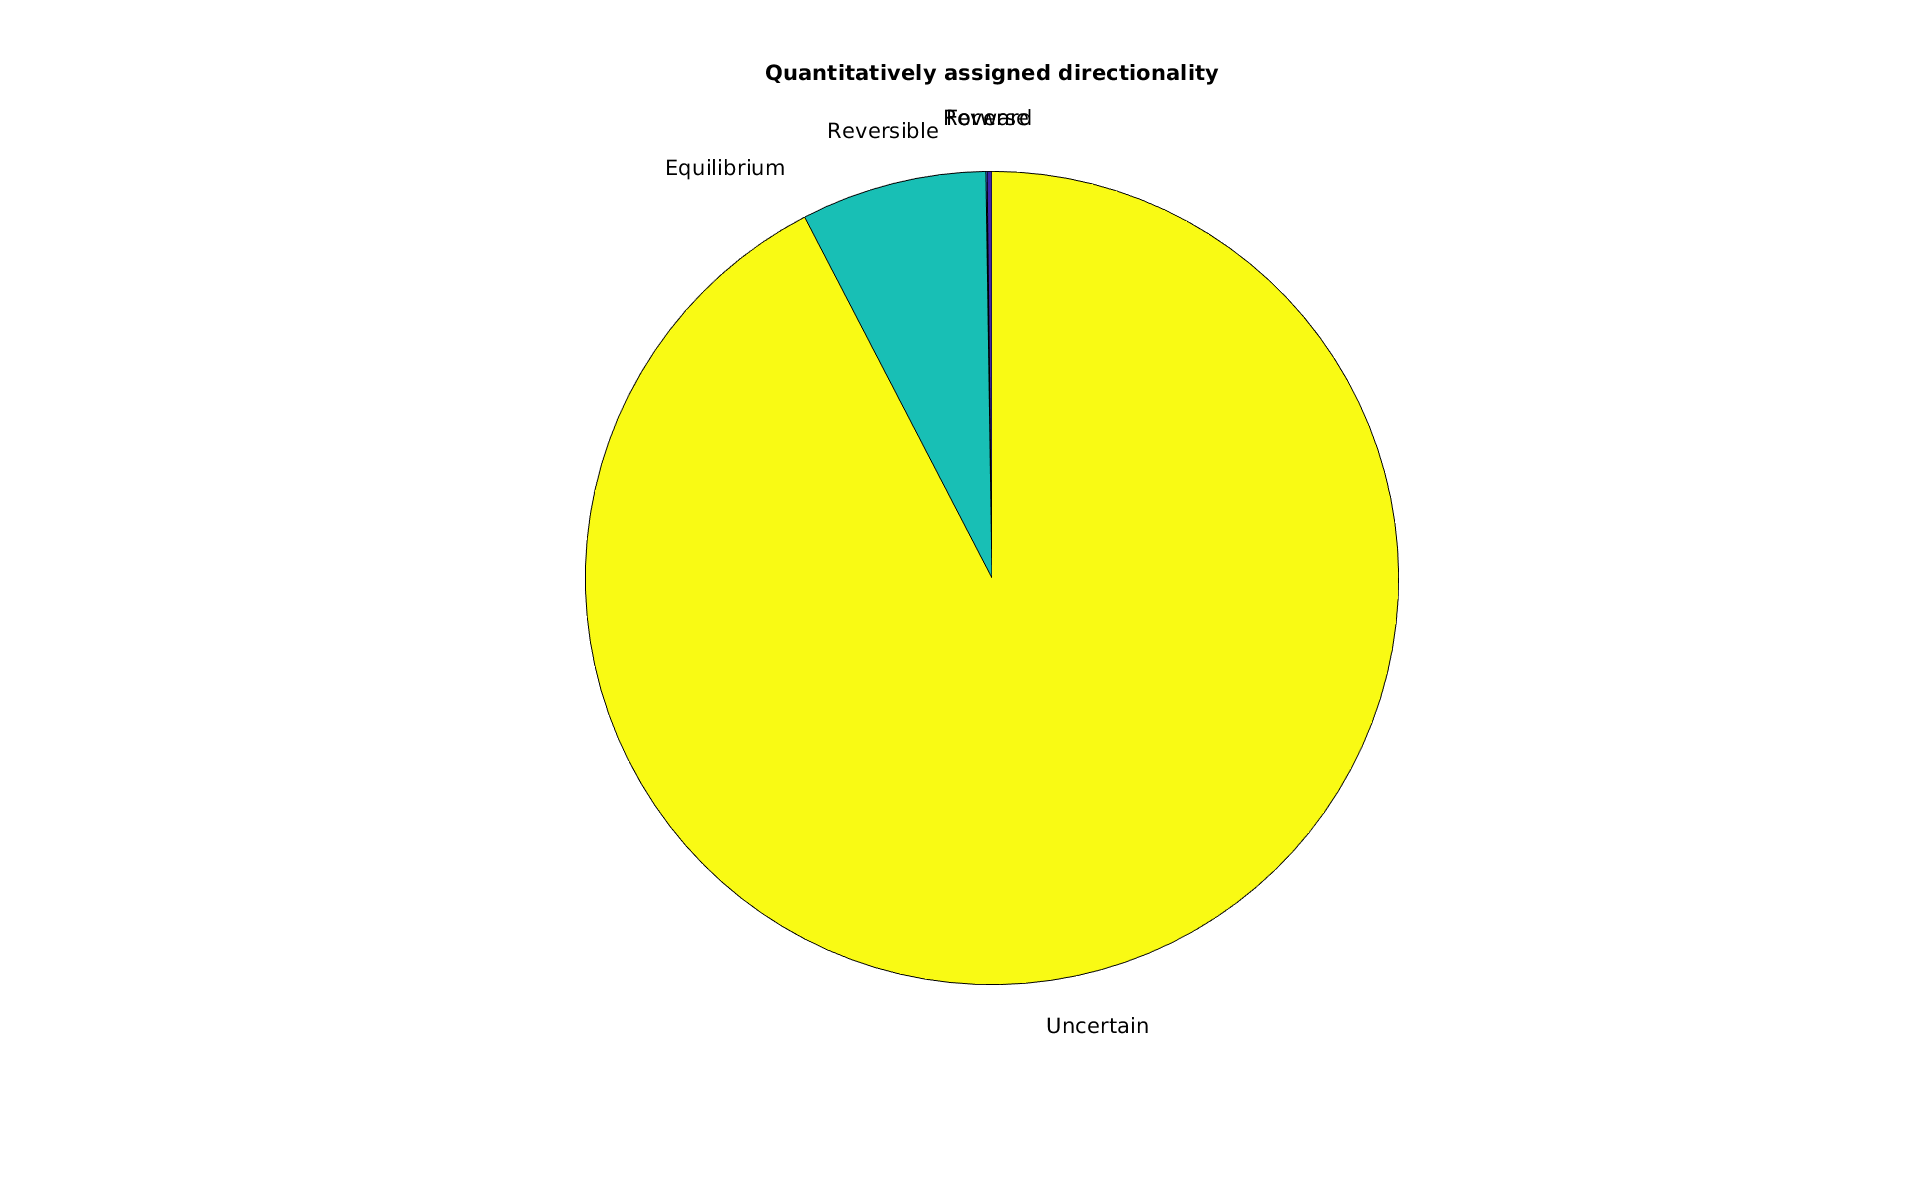

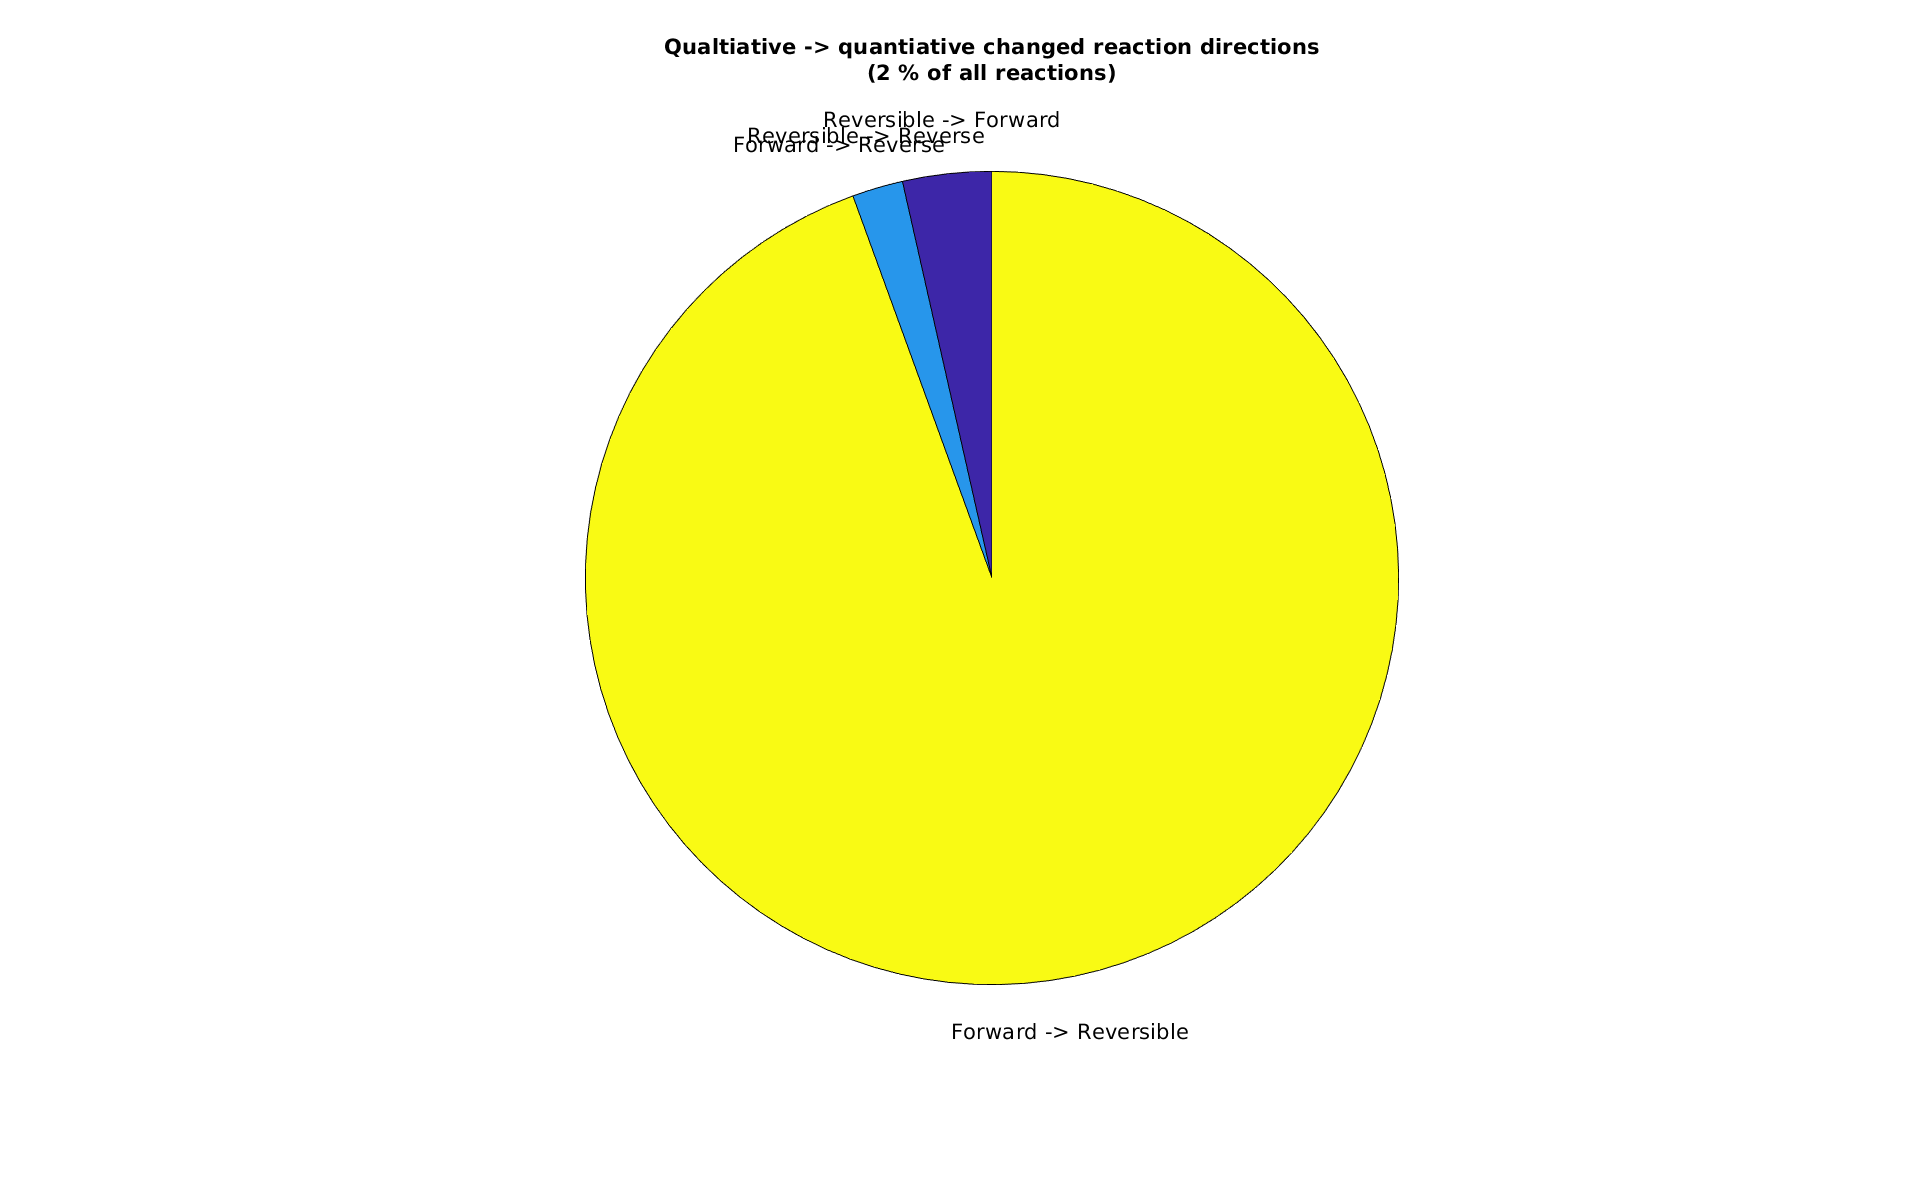

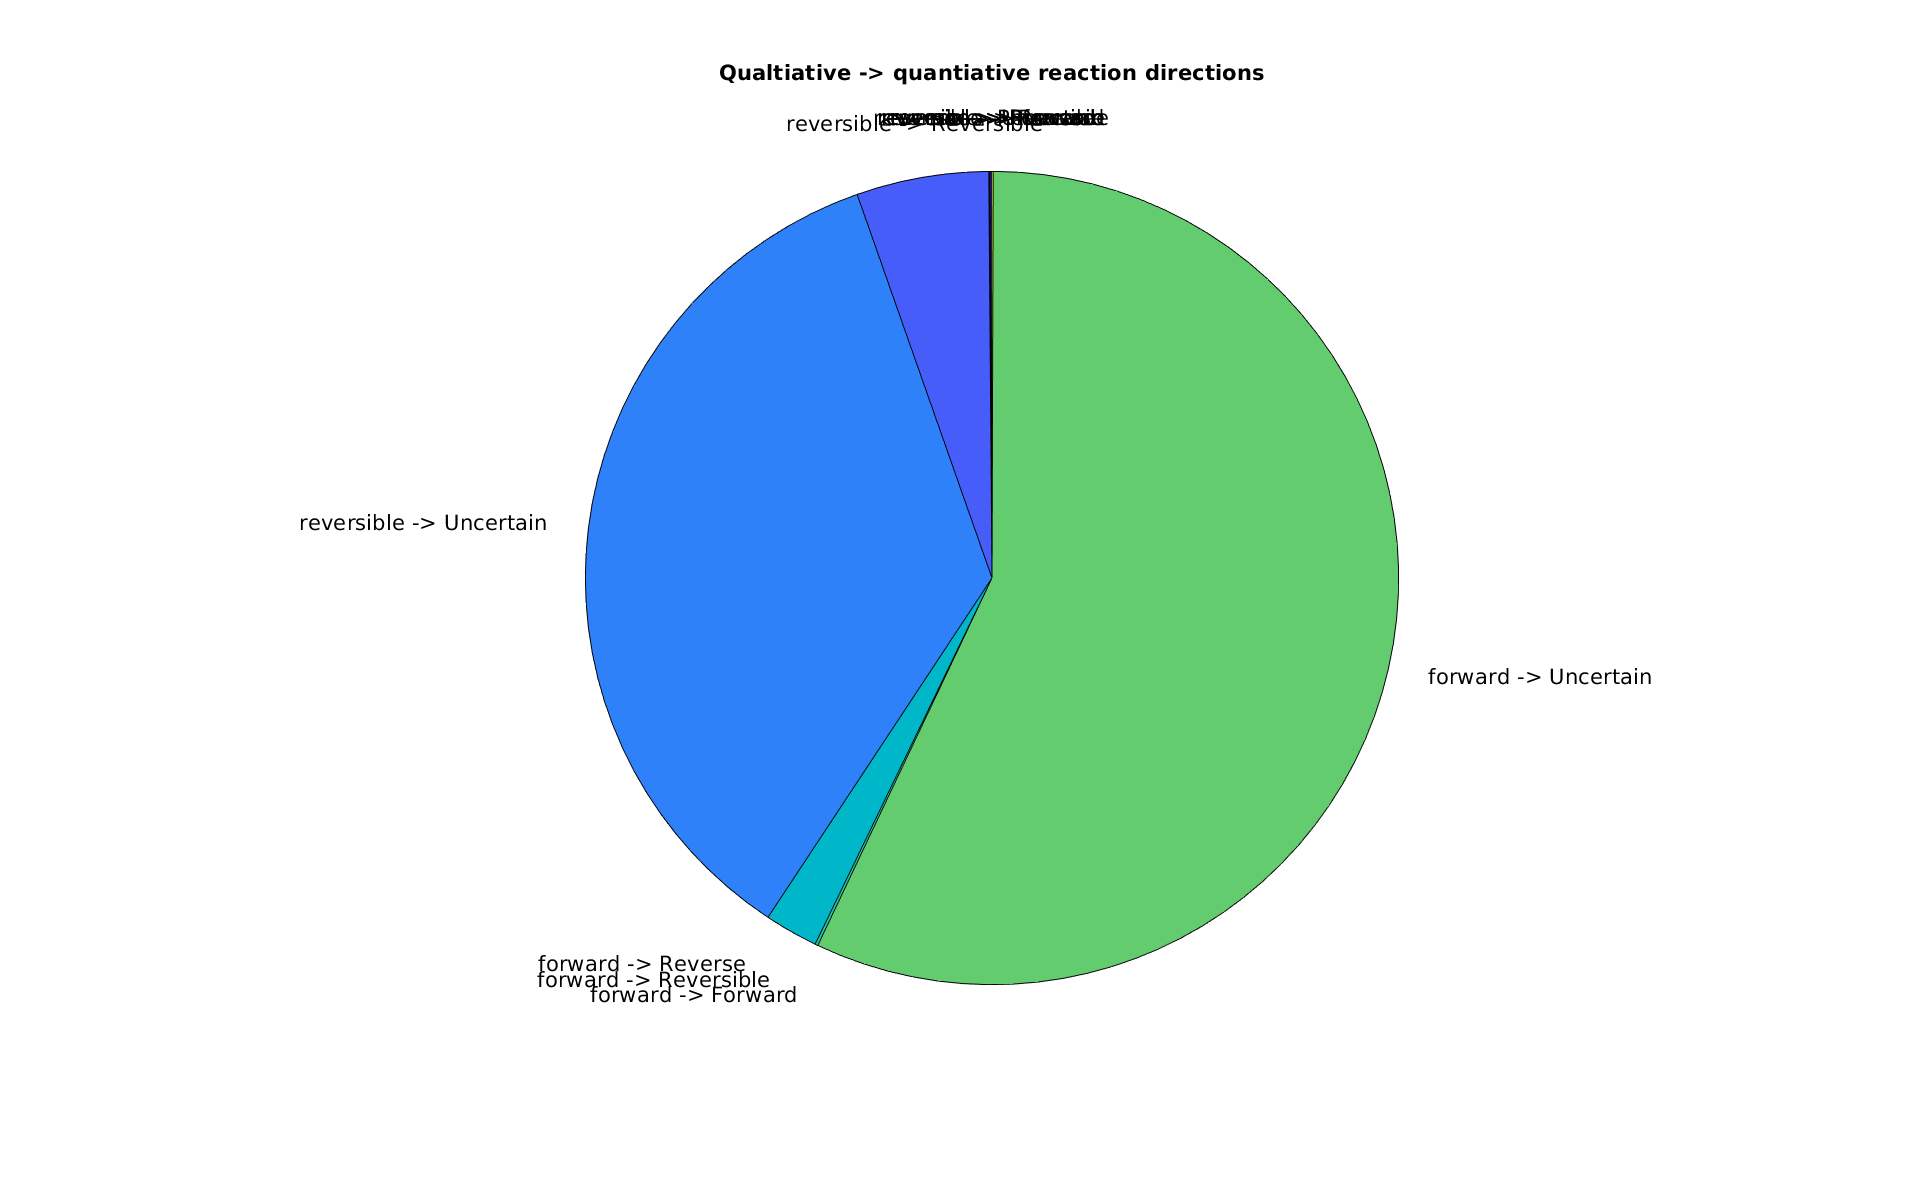

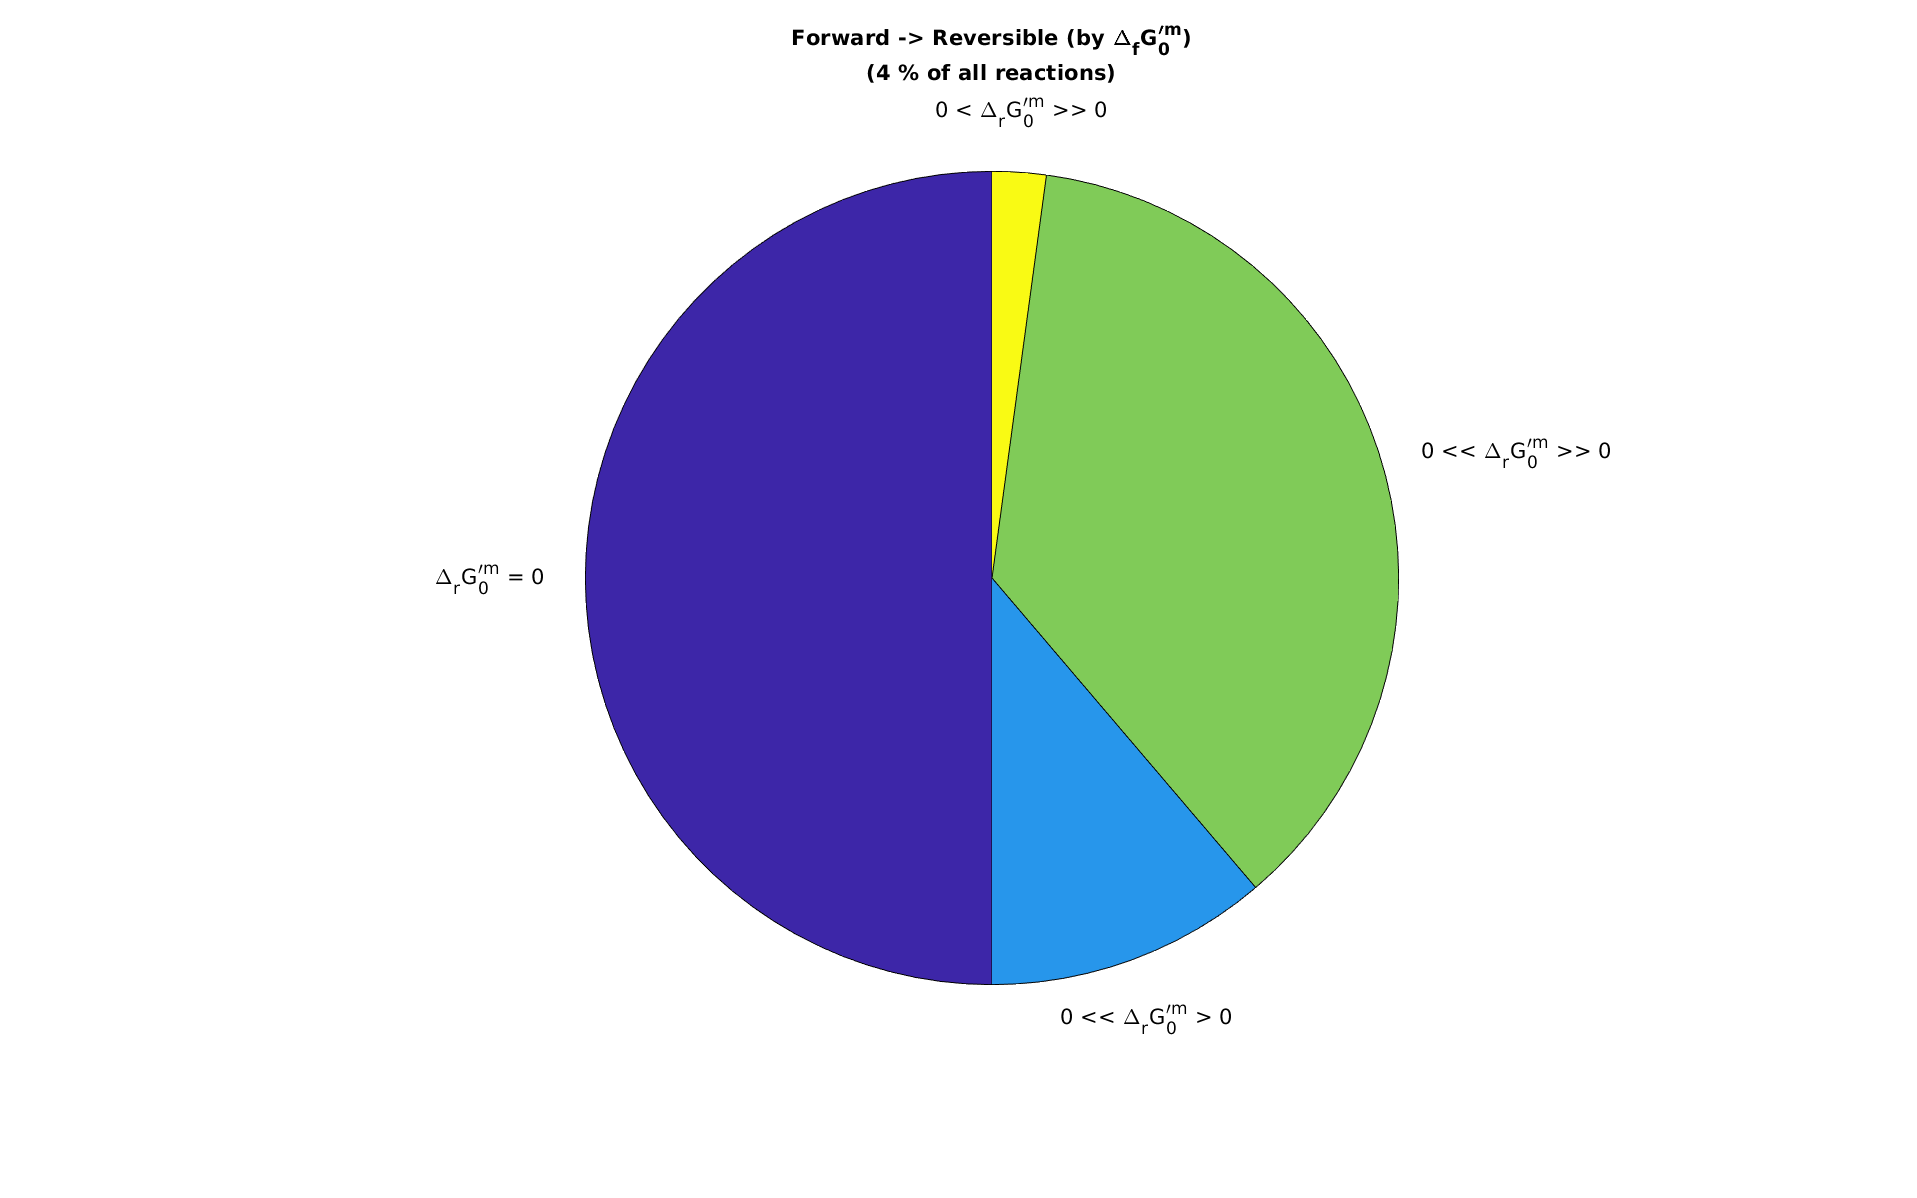

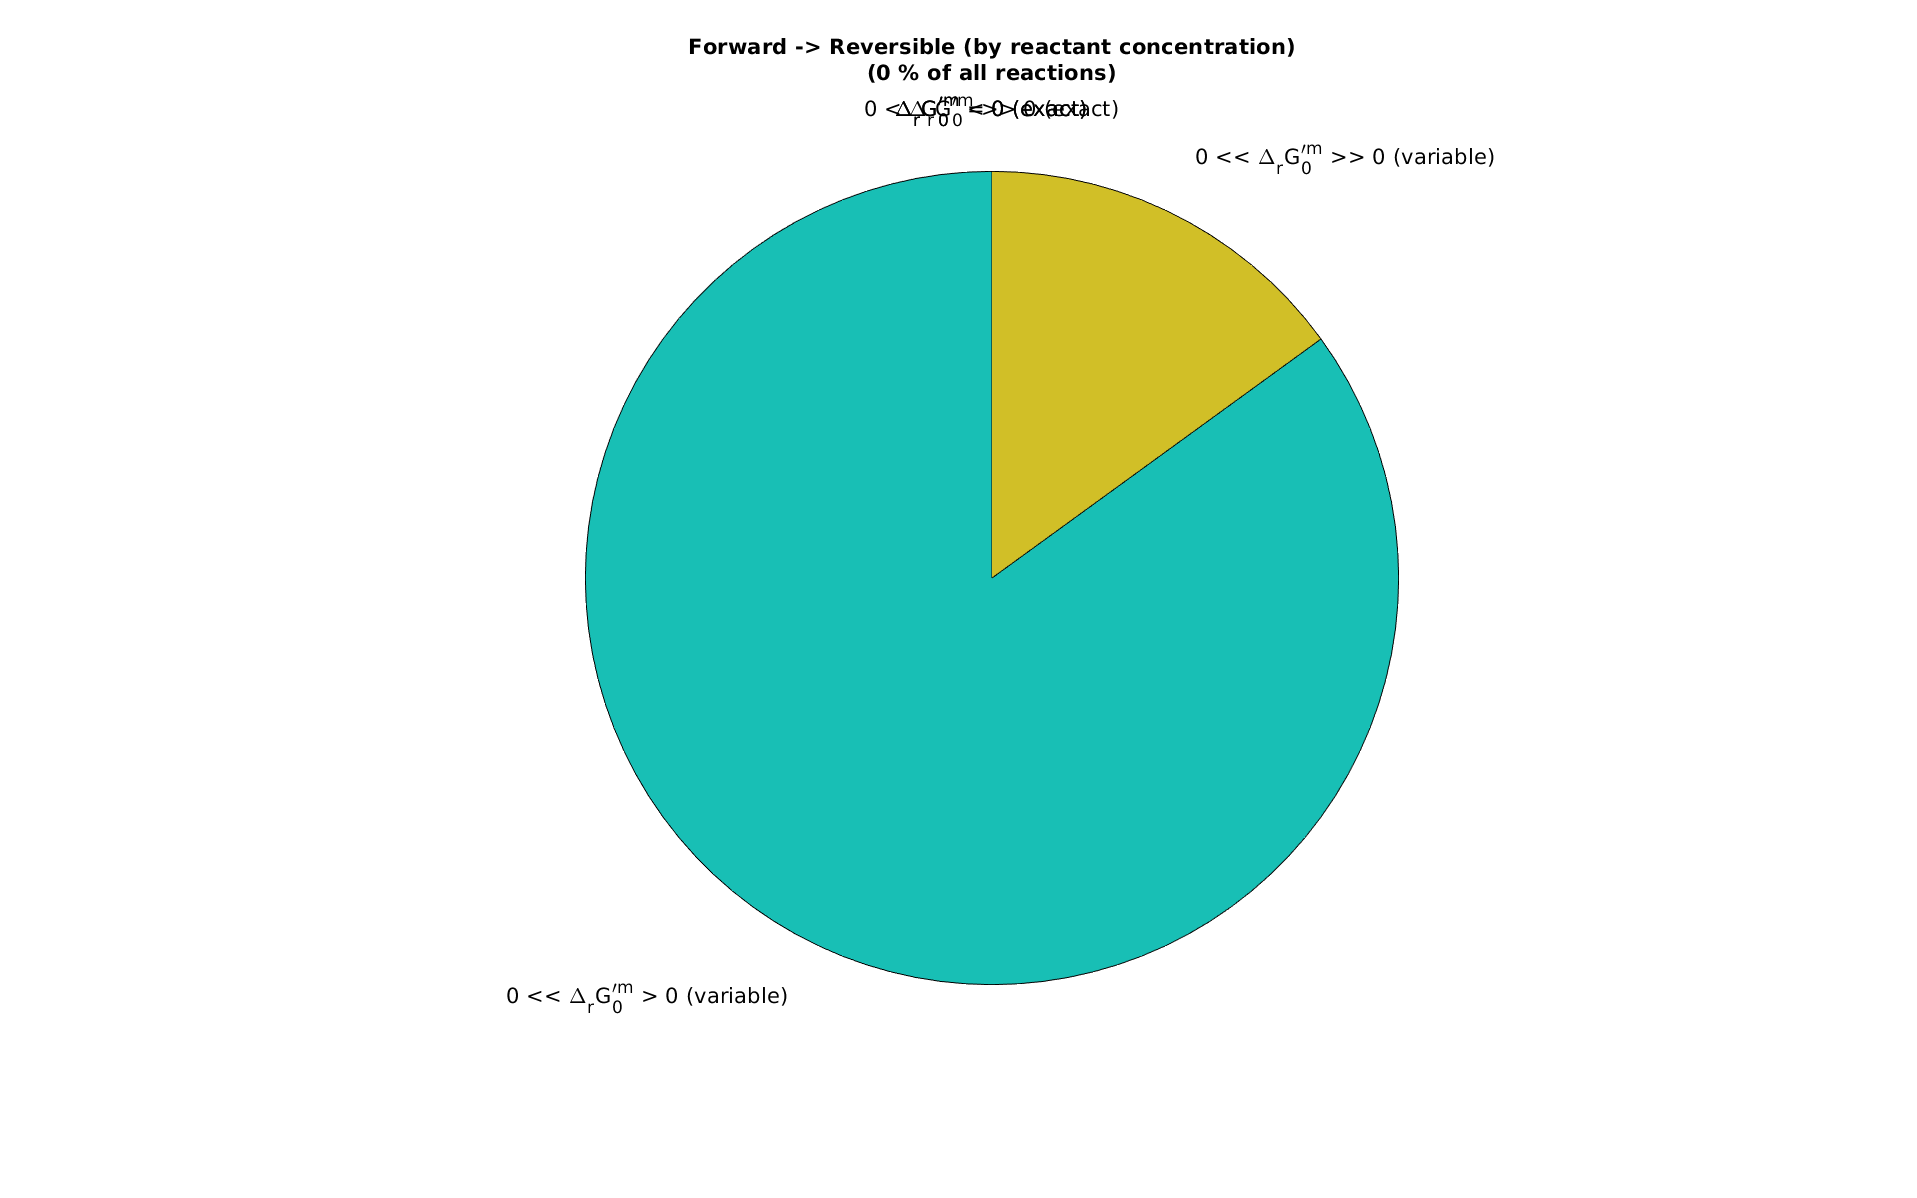

directionalityStatsFigures(directions,resultsBaseFileName)

Generate figures to interpret the overall reasons for reaction directionality changes for the qualitatively forward now quantiatiavely reversible reactions

forwardReversibleFigures...


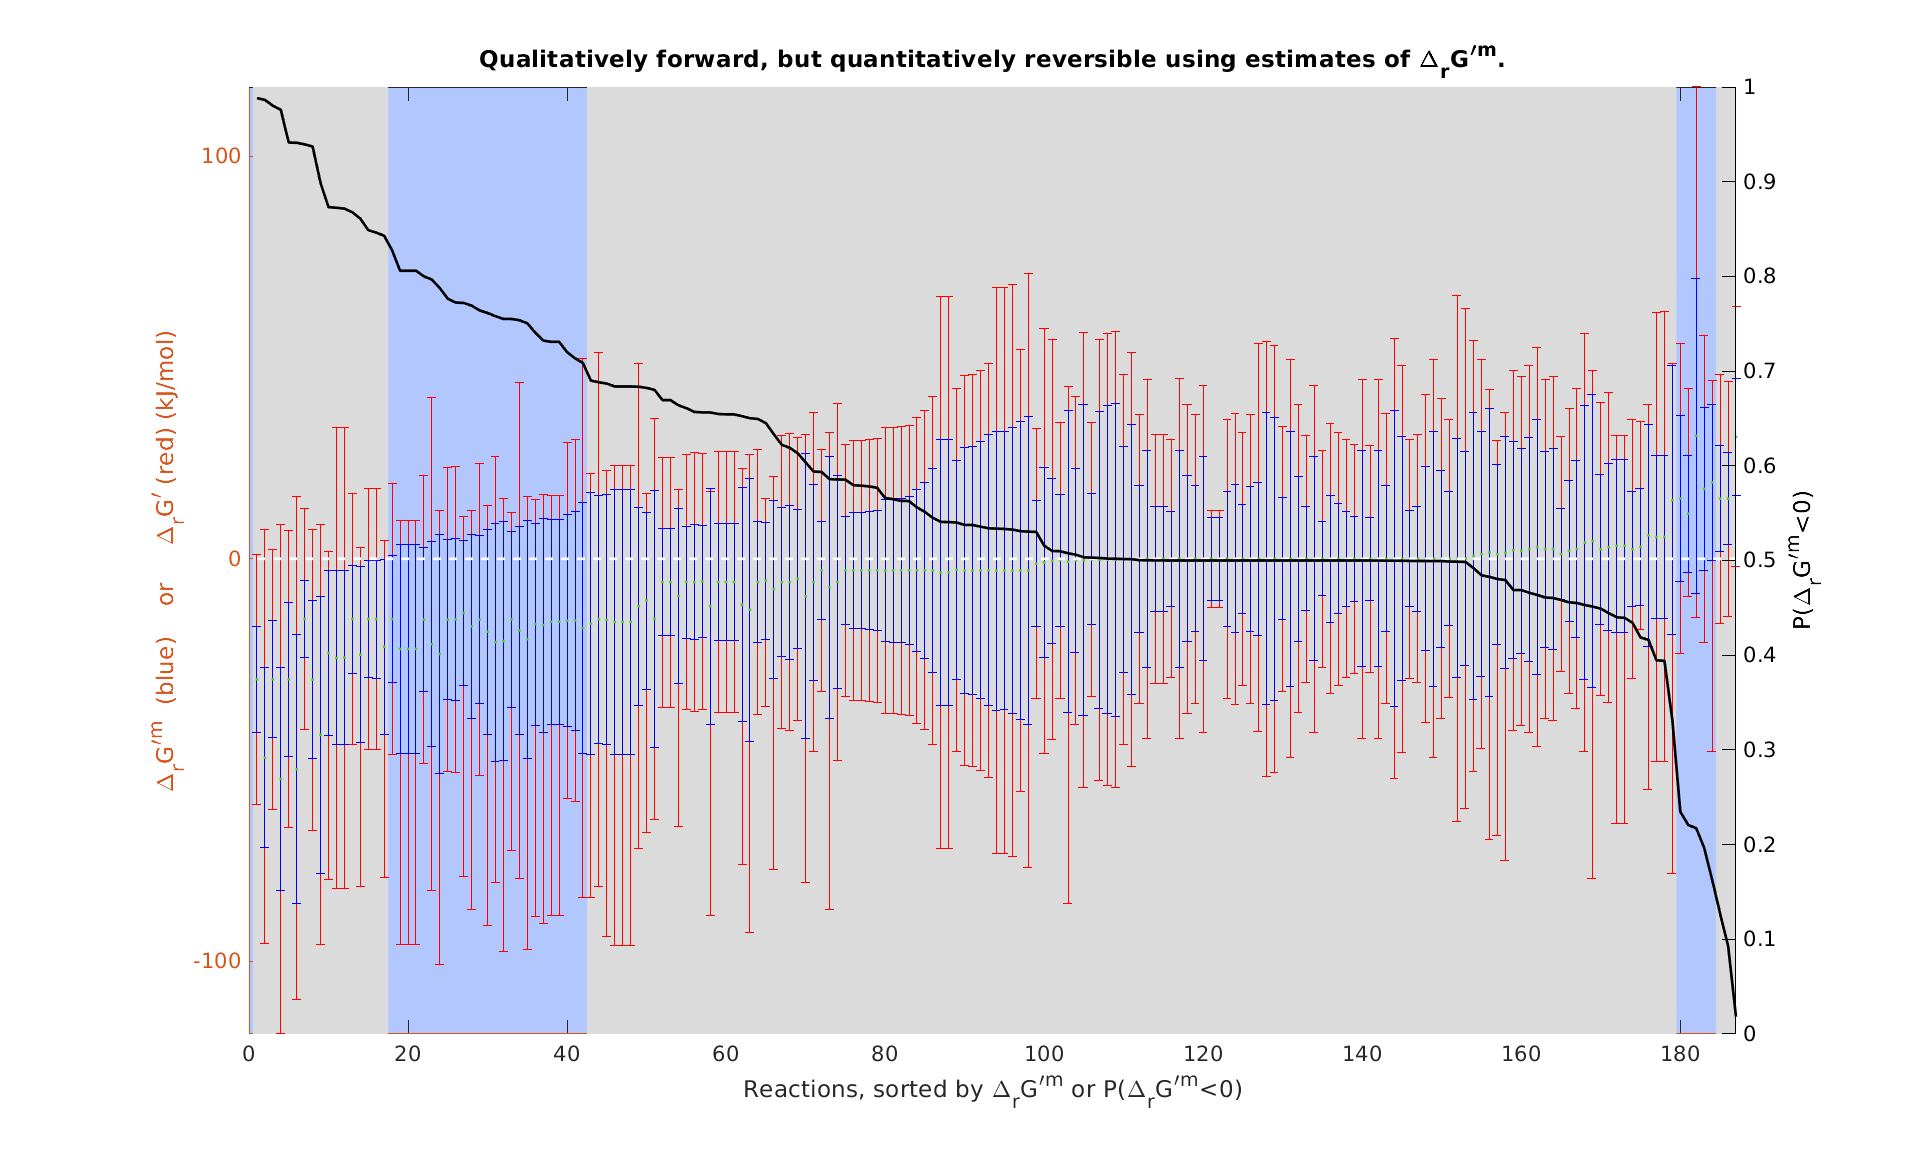

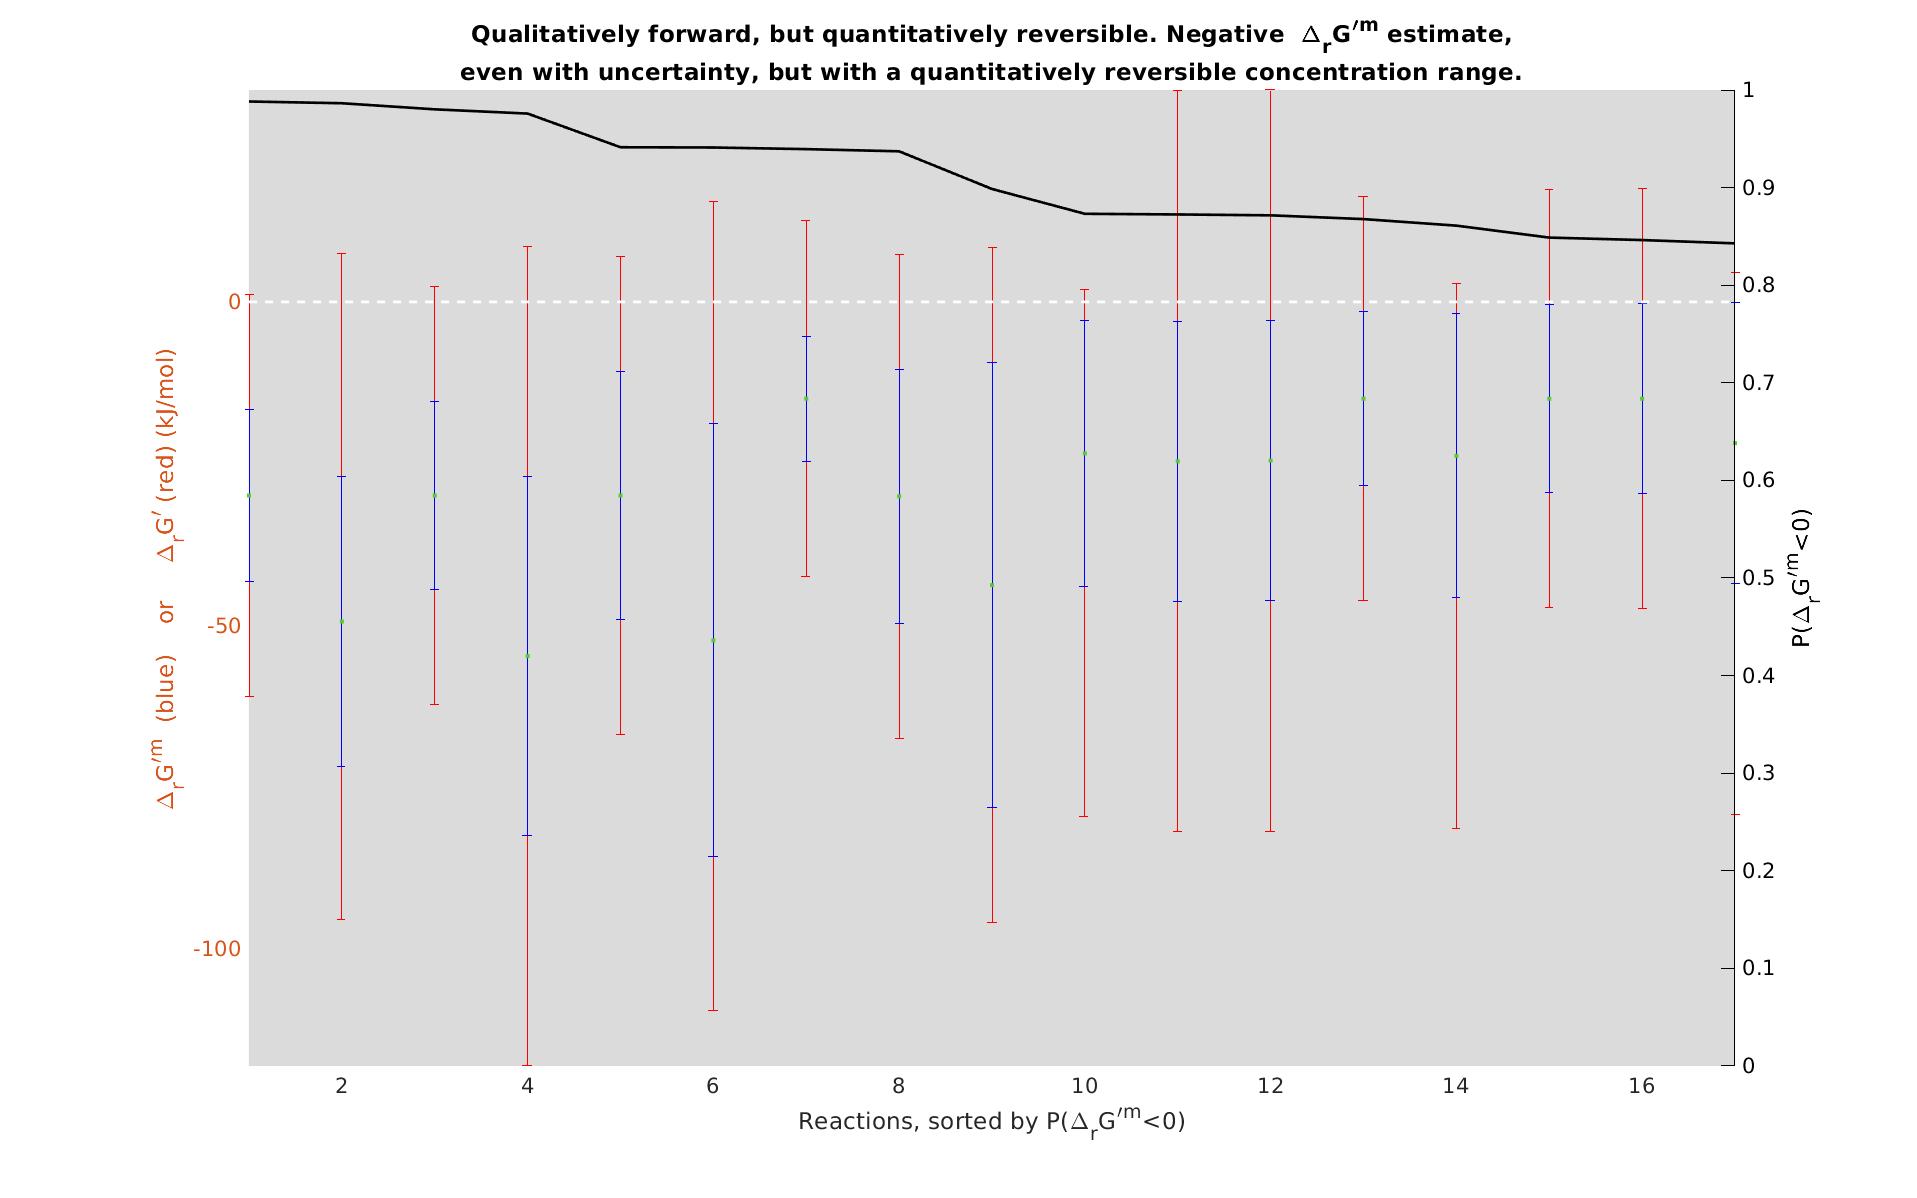

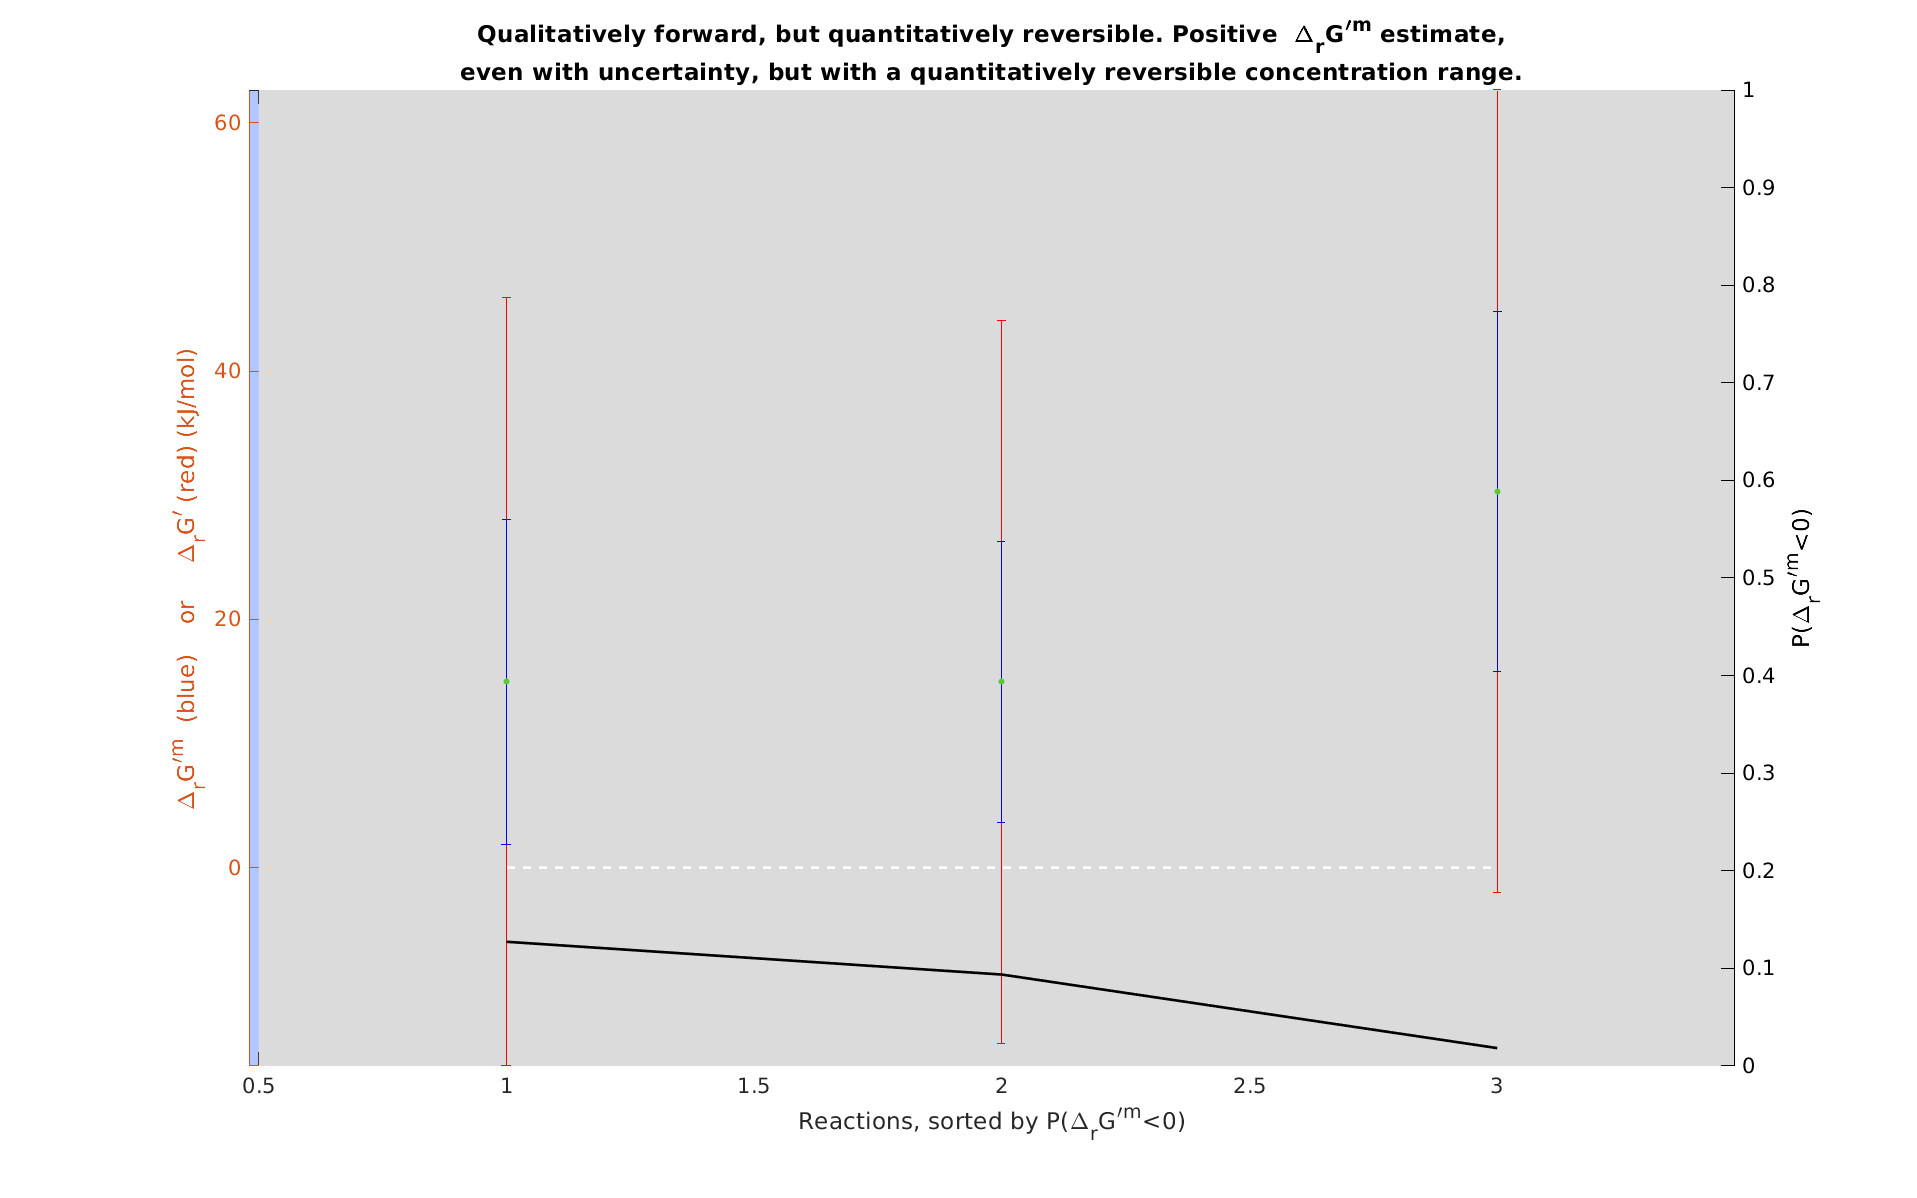

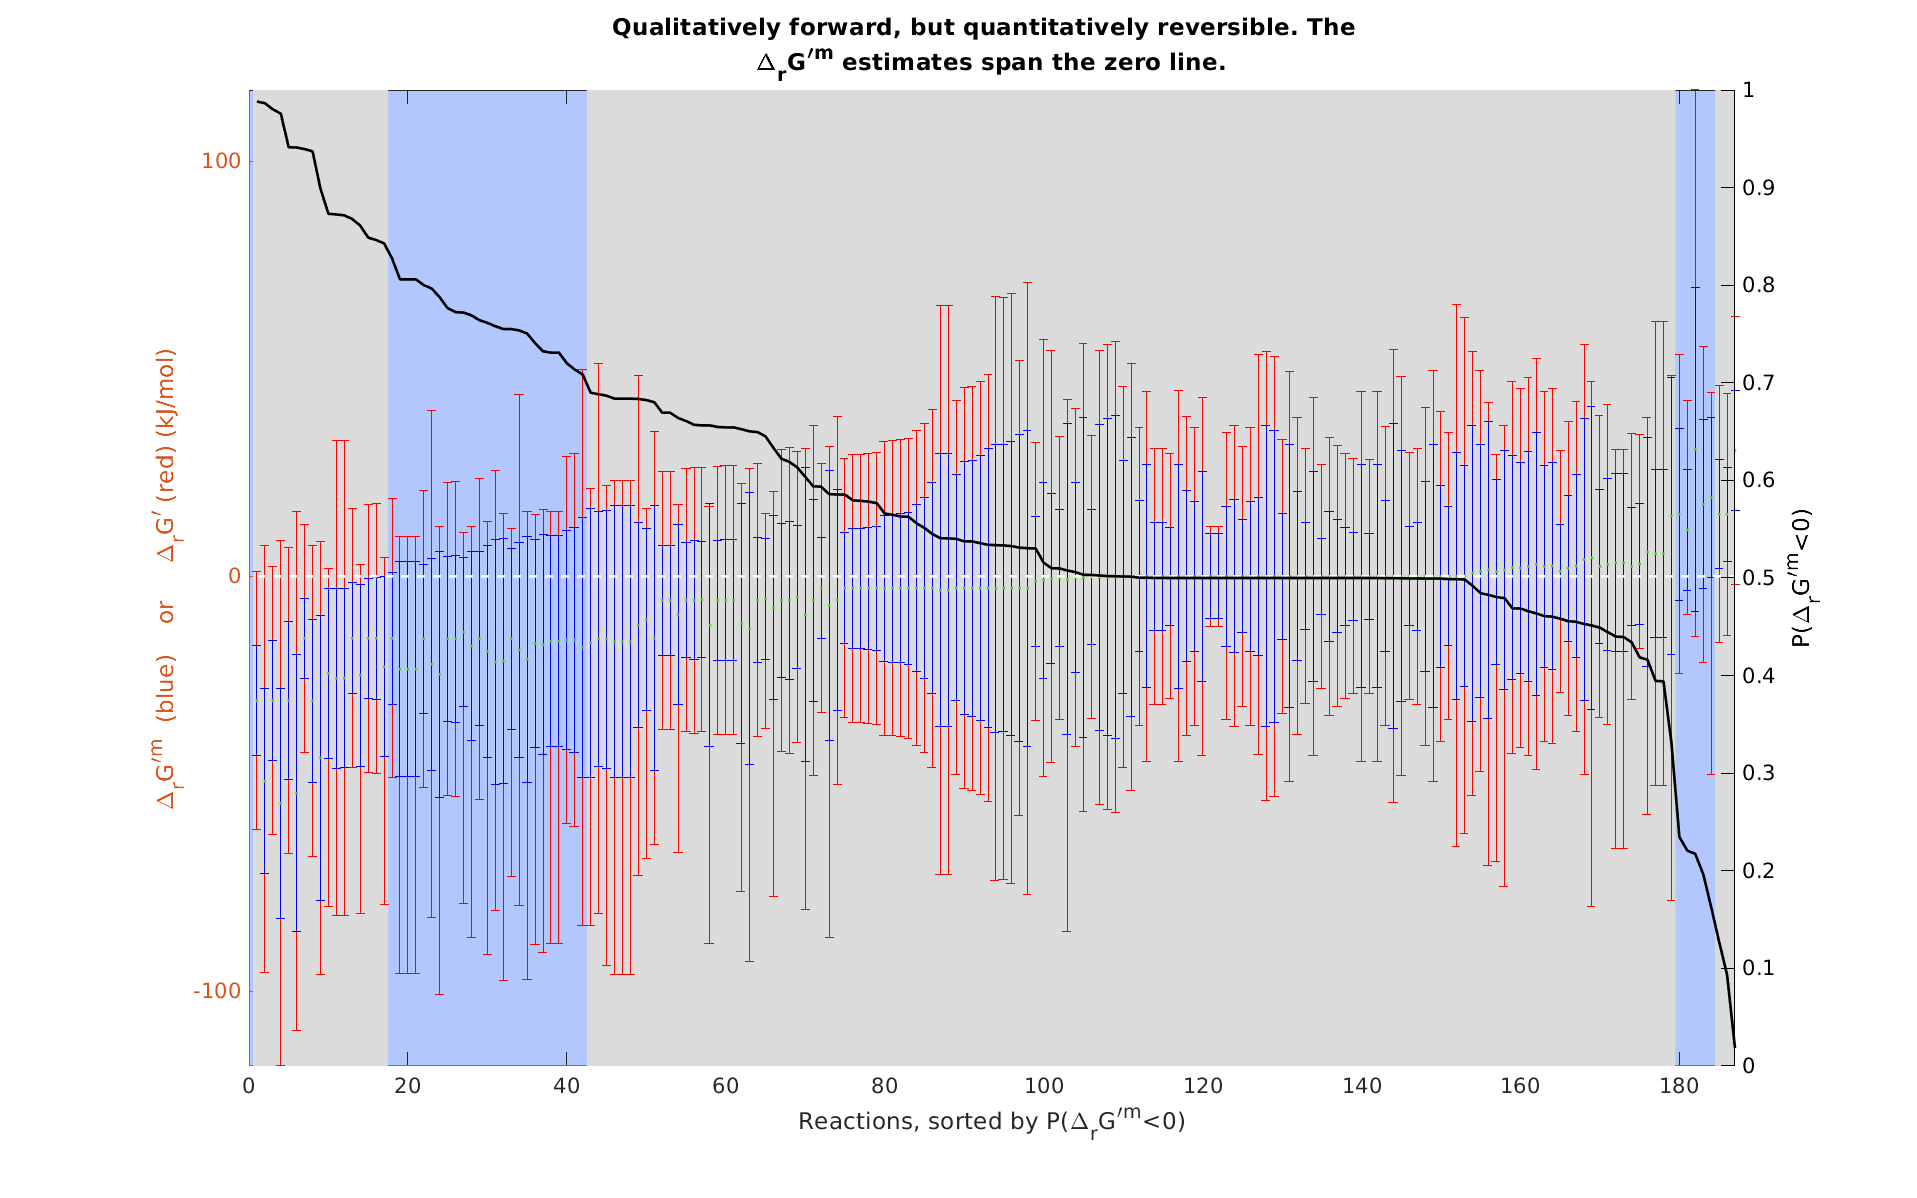

if any(directions.forward2Reversible)
    fprintf('%s\n','forwardReversibleFigures...');
    forwardReversibleFigures(modelThermo,directions,confidenceLevel)
end

Write out tables of experimental and estimated thermochemical parameters for the model

generateThermodynamicTables(modelThermo,resultsBaseFileName);

**REFERENCES**

[1] Fleming, R. M. T. & Thiele, I. von Bertalanffy 1.0: a COBRA toolbox extension to thermodynamically constrain metabolic models. Bioinformatics 27, 142–143 (2011).

[2] Haraldsdóttir, H. S., Thiele, I. & Fleming, R. M. T. Quantitative assignment of reaction directionality in a multicompartmental human metabolic reconstruction. Biophysical Journal 102, 1703–1711 (2012).

[3] Noor, E., Haraldsdóttir, H. S., Milo, R. & Fleming, R. M. T. Consistent Estimation of Gibbs Energy Using Component Contributions. PLoS Comput Biol 9, e1003098 (2013).

[4] Fleming, R. M. T. , Predicat, G.,  Haraldsdóttir, H. S., Thiele, I. von Bertalanffy 2.0 (in preparation).